# Spectrogram Project - Train from Scratch

The data used for this project was obtained from the [University of Iowa Electronic Music Studios](http://theremin.music.uiowa.edu/index.html).

The random seed is so the splitting between training, validation, and testing is consistent. If you are training on a GPU, your networks may not be the same if you train the same network multiple times.

rng(123)

## Load and split data

The images are stored in the folder `Spectrograms`. The data for each instrument is seperated in subfolders, labelled by the folder name.

Split the data so that 80% of the images are used for training, 10% are used for validation, and the rest are used for testing.

imds = imageDatastore('Spectrograms','IncludeSubfolders',true,'LabelSource','foldernames');
[trainImgs,valImgs,testImgs] = splitEachLabel(imds,0.8,0.1,0.1,'randomized');

trainDs = augmentedImageDatastore([227 227],trainImgs);
valDs = augmentedImageDatastore([227 227],valImgs);
testDs = augmentedImageDatastore([227 227],testImgs);

## Series architecture from the documentation

You can find the example that uses this architecture in the documentation here: [Speech Recognition](https://www.mathworks.com/help/nnet/examples/deep-learning-speech-recognition.html#d119e1562)

net=alexnet

net =   SeriesNetwork with properties:

         Layers: [25×1 nnet.cnn.layer.Layer]
     InputNames: {'data'}
    OutputNames: {'output'}


layer = 'fc7';
featuresTrain = activations(net,trainDs,layer,'OutputAs','rows');
featuresTest = activations(net,testDs,layer,'OutputAs','rows');

YTrain = trainImgs.Labels;
YTest = testImgs.Labels;
classifier = fitcecoc(featuresTrain,YTrain);
YPred = predict(classifier,featuresTest);

accuracy = mean(YPred == YTest)

accuracy = 0.9222

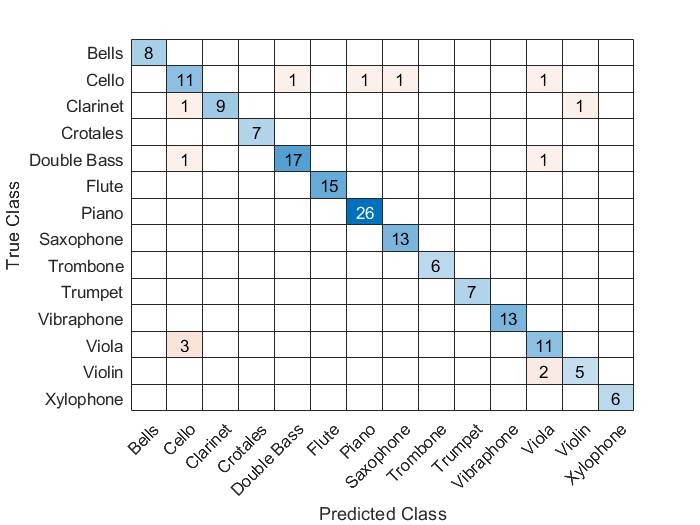

ans =   ConfusionMatrixChart with properties:

    NormalizedValues: [14×14 double]
         ClassLabels: [14×1 categorical]

  Show all properties


confusionchart(YTest,YPred)

## Modify final layers for transfer learning

Replace the fully connected layer and classification layer from AlexNet. There are 14 instruments in this dataset.

ly=net.Layers

ly =   25x1 Layer array with layers:

     1   'data'     Image Input                   227x227x3 images with 'zerocenter' normalization
     2   'conv1'    Convolution                   96 11x11x3 convolutions with stride [4  4] and padding [0  0  0  0]
     3   'relu1'    ReLU                          ReLU
     4   'norm1'    Cross Channel Normalization   cross channel normalization with 5 channels per element
     5   'pool1'    Max Pooling                   3x3 max pooling with stride [2  2] and padding [0  0  0  0]
     6   'conv2'    Grouped Convolution           2 groups of 128 5x5x48 convolutions with stride [1  1] and padding [2  2  2  2]
     7   'relu2'    ReLU                          ReLU
     8   'norm2'    Cross Channel Normalization   cross channel normalization with 5 channels per element
     9   'pool2'    Max Pooling                   3x3 max pooling with stride [2  2] and padding [0  0  0 

lgraph = layerGraph(ly);
ly(end-2) = fullyConnectedLayer(14)

ly =   25x1 Layer array with layers:

     1   'data'     Image Input                   227x227x3 images with 'zerocenter' normalization
     2   'conv1'    Convolution                   96 11x11x3 convolutions with stride [4  4] and padding [0  0  0  0]
     3   'relu1'    ReLU                          ReLU
     4   'norm1'    Cross Channel Normalization   cross channel normalization with 5 channels per element
     5   'pool1'    Max Pooling                   3x3 max pooling with stride [2  2] and padding [0  0  0  0]
     6   'conv2'    Grouped Convolution           2 groups of 128 5x5x48 convolutions with stride [1  1] and padding [2  2  2  2]
     7   'relu2'    ReLU                          ReLU
     8   'norm2'    Cross Channel Normalization   cross channel normalization with 5 channels per element
     9   'pool2'    Max Pooling                   3x3 max pooling with stride [2  2] and padding [0  0  0 

ly(end) = classificationLayer()

ly =   25x1 Layer array with layers:

     1   'data'    Image Input                   227x227x3 images with 'zerocenter' normalization
     2   'conv1'   Convolution                   96 11x11x3 convolutions with stride [4  4] and padding [0  0  0  0]
     3   'relu1'   ReLU                          ReLU
     4   'norm1'   Cross Channel Normalization   cross channel normalization with 5 channels per element
     5   'pool1'   Max Pooling                   3x3 max pooling with stride [2  2] and padding [0  0  0  0]
     6   'conv2'   Grouped Convolution           2 groups of 128 5x5x48 convolutions with stride [1  1] and padding [2  2  2  2]
     7   'relu2'   ReLU                          ReLU
     8   'norm2'   Cross Channel Normalization   cross channel normalization with 5 channels per element
     9   'pool2'   Max Pooling                   3x3 max pooling with stride [2  2] and padding [0  0  0  0]
    1

Training on single CPU.
Initializing input data normalization.


|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|


|       1 |           1 |       00:00:20 |       13.28% |       11.90% |       3.9679 |       3.1443 |          0.0010 |


|       1 |          10 |       00:02:01 |       14.84% |       13.10% |       3.9017 |       2.9028 |          0.0010 |


|       2 |          20 |       00:03:53 |       38.28% |       33.93% |       1.8748 |       1.8337 |          0.0010 |


|       3 |          30 |       00:05:47 |       52.34% |       50.00% |       1.3511 |       1.3626 |          0.0010 |


|       4 |          40 |       00:07:40 |       60.16% |       60.12% |       1.2546 |       1.3675 |          0.0010 |


|       5 |          50 |       00:09:31 |       69.53% |       75.60% |       1.0064 |       0.7697 |          0.0010 |


|       6 |          60 |       00:11:29 |       78.13% |       79.17% |       0.7050 |       0.6068 |          0.0010 |


|       7 |          70 |       00:13:25 |       79.69% |       84.52% |       0.6234 |       0.5023 |          0.0010 |


|       8 |          80 |       00:15:24 |       85.16% |       87.50% |       0.5246 |       0.3775 |          0.0010 |


|       9 |          90 |       00:17:22 |       84.38% |       86.90% |       0.4983 |       0.3876 |          0.0010 |


|      10 |         100 |       00:19:17 |       86.72% |       87.50% |       0.5282 |       0.4435 |          0.0010 |


|      11 |         110 |       00:21:14 |       86.72% |       90.48% |       0.3654 |       0.3267 |          0.0001 |


|      12 |         120 |       00:23:08 |       90.63% |       94.64% |       0.3341 |       0.1978 |          0.0001 |


|      13 |         130 |       00:25:00 |       90.63% |       94.05% |       0.2503 |       0.1978 |          0.0001 |


|      14 |         140 |       00:26:52 |       92.19% |       95.24% |       0.2690 |       0.1831 |          0.0001 |


|      15 |         150 |       00:29:27 |       90.63% |       95.24% |       0.2483 |       0.1744 |          0.0001 |


|      16 |         160 |       00:31:50 |       92.97% |       95.83% |       0.2378 |       0.1632 |          0.0001 |


|      17 |         170 |       00:34:11 |       94.53% |       95.83% |       0.1865 |       0.1589 |          0.0001 |


|      18 |         180 |       00:36:28 |       93.75% |       97.02% |       0.1959 |       0.1525 |          0.0001 |


|      19 |         190 |       00:38:39 |       96.09% |       96.43% |       0.1488 |       0.1473 |          0.0001 |


|      20 |         200 |       00:40:33 |       93.75% |       97.02% |       0.1842 |       0.1351 |          0.0001 |


|      21 |         210 |       00:42:23 |       96.09% |       97.02% |       0.1479 |       0.1356 |      1.0000e-05 |


|      22 |         220 |       00:44:18 |       96.09% |       97.02% |       0.1369 |       0.1376 |      1.0000e-05 |


|      23 |         230 |       00:46:12 |       95.31% |       97.02% |       0.1591 |       0.1398 |      1.0000e-05 |


|      24 |         240 |       00:48:25 |       93.75% |       97.02% |       0.1679 |       0.1404 |      1.0000e-05 |


|      25 |         250 |       00:50:59 |       96.88% |       97.02% |       0.1347 |       0.1409 |      1.0000e-05 |


|      26 |         260 |       00:53:44 |       95.31% |       97.02% |       0.1406 |       0.1396 |      1.0000e-05 |


|      27 |         270 |       00:56:55 |       96.09% |       97.02% |       0.1414 |       0.1397 |      1.0000e-05 |


|      28 |         280 |       01:00:23 |       97.66% |       97.02% |       0.1210 |       0.1399 |      1.0000e-05 |


|      29 |         290 |       01:03:13 |       96.09% |       97.02% |       0.1374 |       0.1398 |      1.0000e-05 |


|      30 |         300 |       01:06:01 |       96.88% |       97.02% |       0.1336 |       0.1393 |      1.0000e-05 |


|======================================================================================================================|


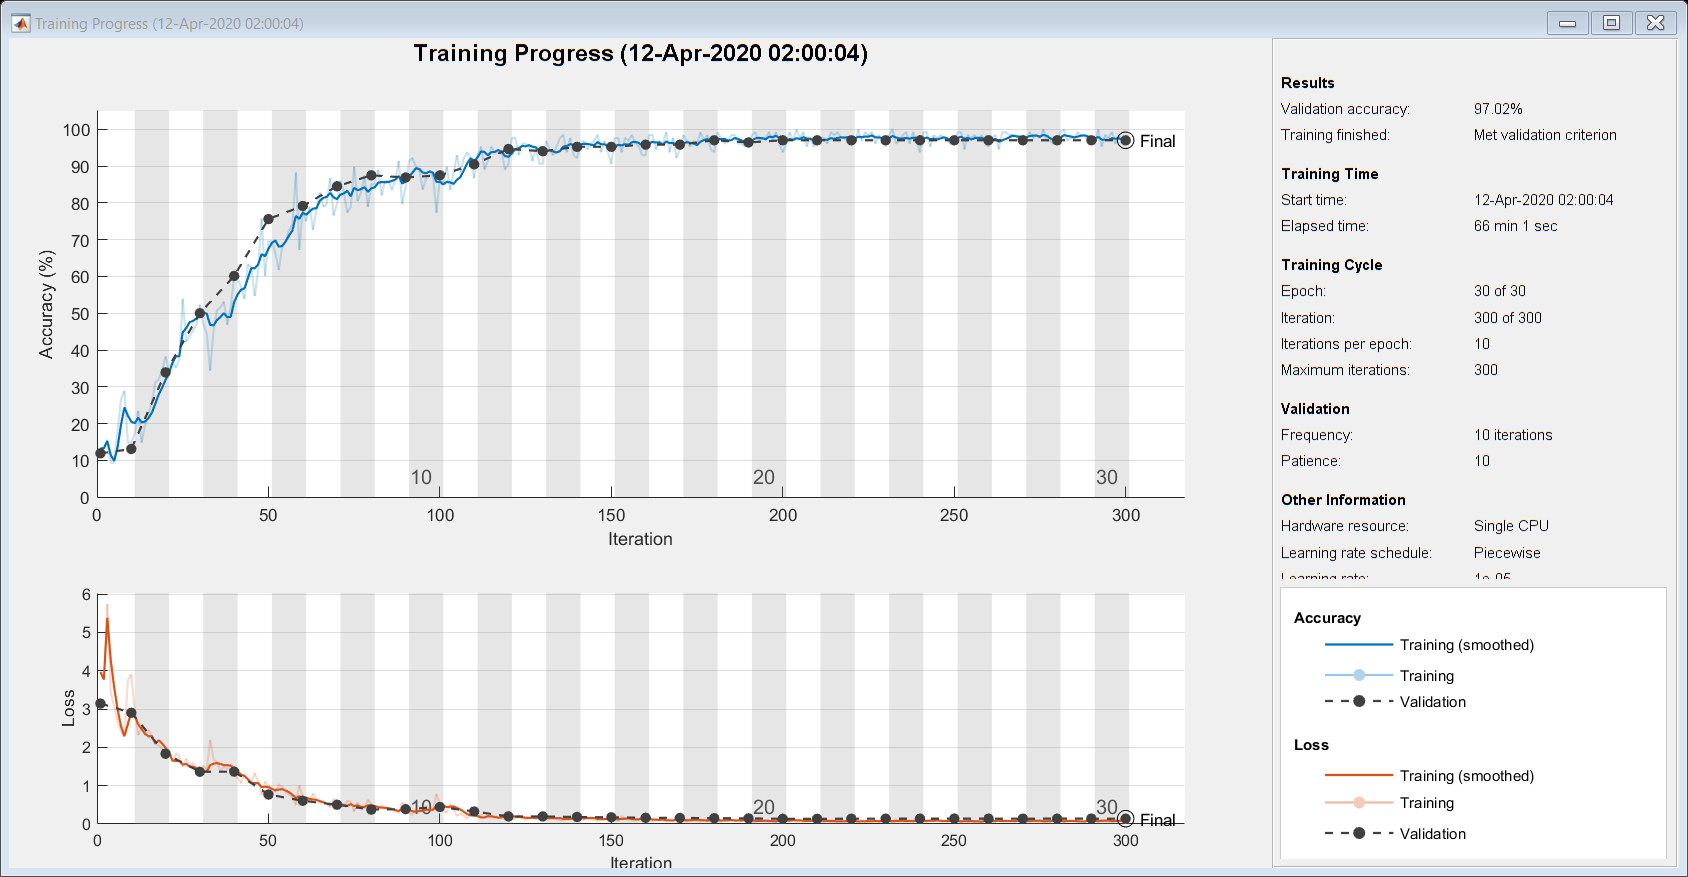

instnet =   SeriesNetwork with properties:

         Layers: [25×1 nnet.cnn.layer.Layer]
     InputNames: {'data'}
    OutputNames: {'classoutput'}



options = trainingOptions('adam','MaxEpochs',30,'InitialLearnRate',0.001,...
    'Plots','training-progress','ValidationData',valDs,'ValidationFrequency',10,'ValidationPatience',10,"LearnRateSchedule",'piecewise','LearnRateDropPeriod',10,'LearnRateDropFactor',0.1);

instnet = trainNetwork(trainDs,ly,options)


testPreds = classify(instnet,testDs);
accuracy2 = mean(testPreds == YTest)

accuracy2 = 0.8982

Plot confusion matrix